# Basic Water Injection Examples

This notebook covers the basic functionalities of simulating water injection in different reservoirs, employing the black oil model, in particular, SPE1. The goal is to ...... 

To begin, execute Ctrl+Enter in this section to clear all variables of the session.

clear;
mrstModule add ad-core ad-blackoil ad-props test-suite mrst-gui
gravity reset on
[~, ~, fluid, deck] = setupSPE1();
fluid.krW = @(s) s.^2;

## Grid Setup

In this section, we set up the grid, the rock, and the initial properties, including dissolved gas is oil, initial water, oil and gas saturations.

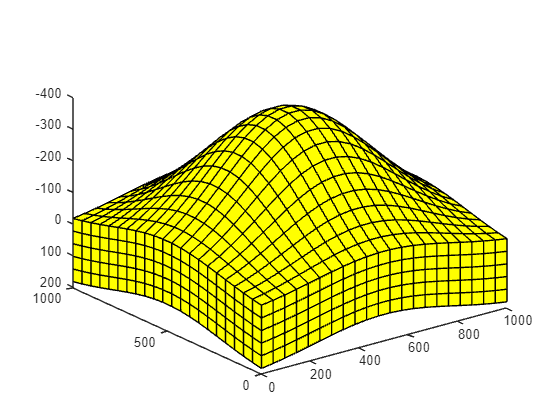

len = 1000;
num_cell = 20;
range = 0:(len/num_cell):len;
x = range';
y = range;
for i = 1:(length(range) - 1)
    x = [x range'];
    y = [y; range];
end

thickness = 200;
number_of_layers = 5;
nd = 400;

z = zeros(length(range));

for i = 1:(length(range))
    for j = 1:(length(range))
        z(i, j) = -nd*exp(-((x(i, j) - (len/2))^2 + (y(i, j) - (len/2))^2)/(nd^2));
    end
end

horizons = {struct('x',x,'y',y,'z',z),struct('x',x,'y',y,'z',z + thickness)};
grdecl = convertHorizonsToGrid(horizons,'layers', number_of_layers);
G = processGRDECL(grdecl);

G = computeGeometry(G);
rock = makeRock(G, 0.3*darcy, 0.3);

s0 = [0.2, 0.8, 0]; % WOG saturation
p0 = 300*barsa; % Initial pressure
state0 = initResSol(G, p0, s0);
state0.rs = repmat(200, G.cells.num, 1); % 200 Rs, dissolved gas in oil ratio
model = ThreePhaseBlackOilModel(G, rock, fluid, 'disgas', true); % Black oil with disgas

clf; plotGrid(G); view(3)

## Driving mechanisms

In this section, we set up the simulation time, timesteps, the well position, the type of operation (fixed bhp, in this case).

T = 200*day;
dt = rampupTimesteps(T, 10*day, 4);

ij = ceil(G.cartDims./2);
% a = ij(1);
% b = ij(2);
a = 11;
b = 11;
W = verticalWell([], G, rock, a, b, [], ...
    'val',      400*barsa, ...
    'type',     'bhp',...
    'comp_i',   [1 0 0], ...
    'sign',     1, ...
    'name',     'inj');

schedule = simpleSchedule(dt, 'W', W);

## Plot Grid and Well

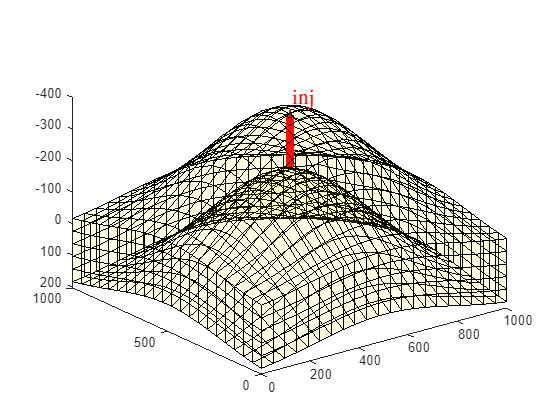

clf;plotGrid(G, 'FaceAlpha', 0.05); plotWell(G,W,'height',0); view(3);

## Run simulation

[ws, states] = simulateScheduleAD(state0, model, schedule);

Solving timestep 01/24:          -> 15 Hours
Solving timestep 02/24: 15 Hours -> 1 Day, 6 Hours
Solving timestep 03/24: 1 Day, 6 Hours -> 2 Days, 12 Hours
Solving timestep 04/24: 2 Days, 12 Hours -> 5 Days
Solving timestep 05/24: 5 Days   -> 10 Days
Solving timestep 06/24: 10 Days  -> 20 Days
Solving timestep 07/24: 20 Days  -> 30 Days
Solving timestep 08/24: 30 Days  -> 40 Days
Solving timestep 09/24: 40 Days  -> 50 Days
Solving timestep 10/24: 50 Days  -> 60 Days
Solving timestep 11/24: 60 Days  -> 70 Days
Solving timestep 12/24: 70 Days  -> 80 Days
Solving timestep 13/24: 80 Days  -> 90 Days
Solving timestep 14/24: 90 Days  -> 100 Days
Solving timestep 15/24: 100 Days -> 110 Days
Solving timestep 16/24: 110 Days -> 120 Days
Solving timestep 17/24: 120 Days -> 130 Days
Solving timestep 18/24: 130 Days -> 140 Days
Solving timestep 19/24: 140 Days -> 150 Days
Solving timestep 20/24: 150 Days -> 160 Days
Solving timestep 21/24: 160 Days -> 170 Days
Solving timestep 22/24: 170 Days -> 18

## Plot Data of Interest

Injection Rate:

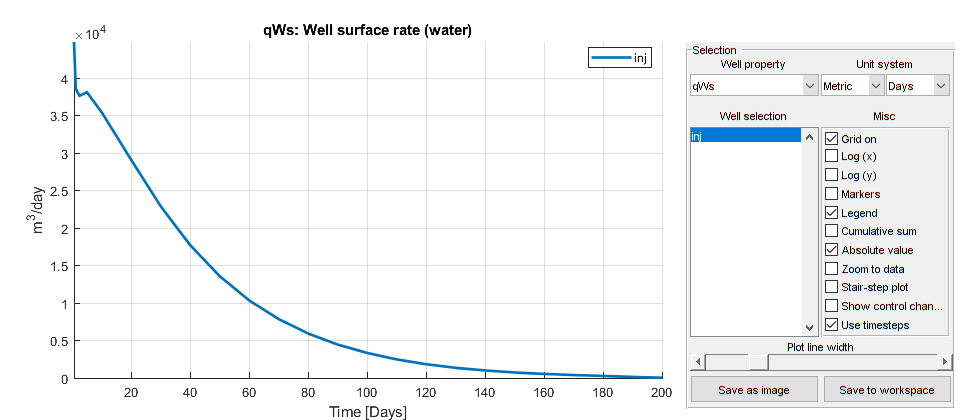

plotWellSols(ws, cumsum(schedule.step.val),'field','qWs')

Reservoir State:

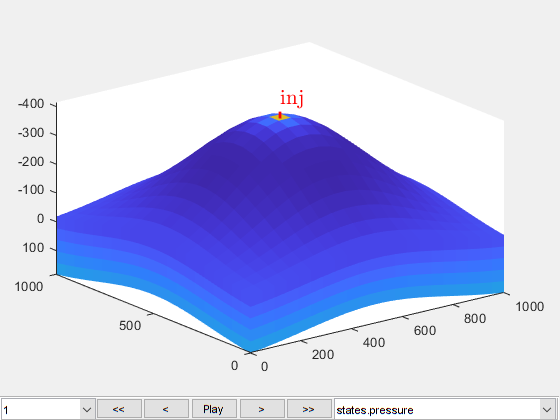

figure;plotToolbar(G,states); plotWell(G,W,'height',20); view(3); axis tight